## Polar Overturning Conceptual Model

#### Live script to run experiments in paper and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening.

model1 = build_POC_model('NH_FSBSO_can') ;

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.1028   0.2689   0.6421
 Polar    Water:                     -1.8675          |           34.3235          |  -1.7039  -1.0863  -0.0000
 Overflow Water:             1.2043   1.4288   1.5674 |  34.9022  34.9549  35.0714 |  -4.7261  -3.6699  -3.0705
 Shelf    Water:            -1.9941  -2.0607  -2.2015 |  36.4907  37.6234  40.0000 |  -0.5902  -0.2291  -0.0747
 Ambient

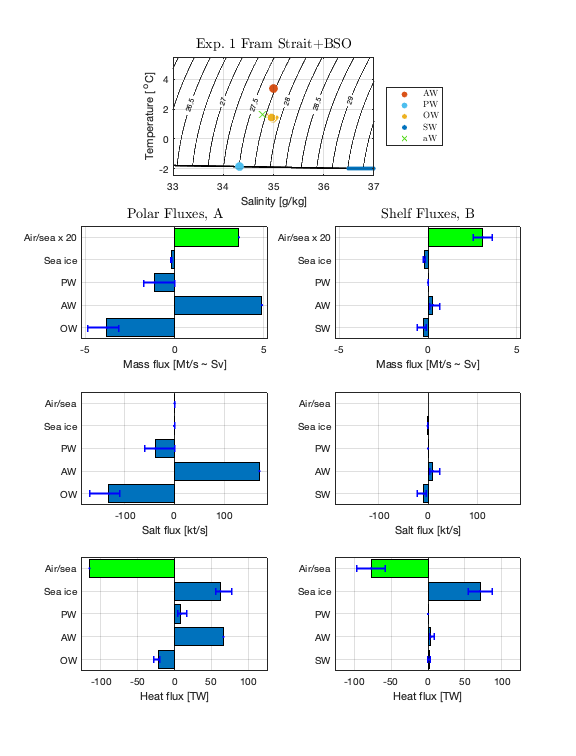

plot_POC_solution(model1)

Exp 2: Modified Northern hemisphere Fram Strait/Barents Sea Opening (higher Q).

model2 = build_POC_model('NH_FSBSO_mod') ;

 Solutions for experiment: [Exp.~2 Fram Strait+BSO high ${\cal Q}$] with file suffices: [NH_FSBSO_mod]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   2.9485   3.3072   3.6926
 Polar    Water:                     -1.8675          |           34.3235          |  -1.8285  -0.9941  -0.0031
 Overflow Water:            -1.8932  -1.4517  -1.0728 |  34.7652  34.8222  34.8816 |  -4.7432  -3.7762  -2.9606
 Shelf    Water:            -1.8932  -1.8969  -1.9019 |  34.7652  34.8287  34.9134 |  -3.6813  -3.3036  

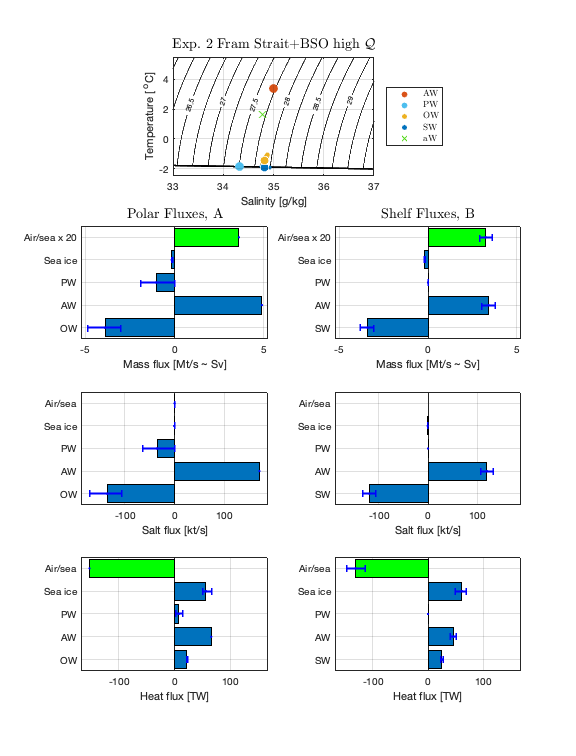

plot_POC_solution(model2) ;

Make figure showing entrainment/shelf circulation tradeoff

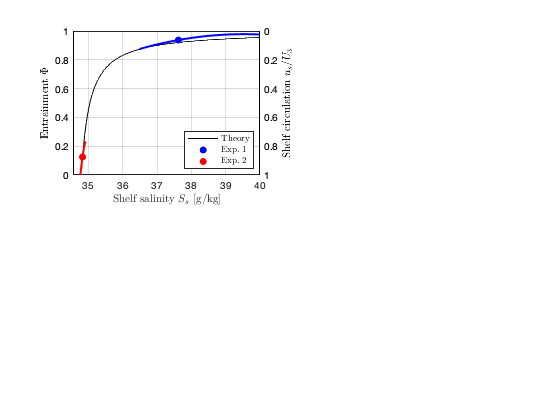

plot_POC_tradeoff(model1,model2)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3 = build_POC_model('NH_FSBSO_range') ;

 Solutions for experiment: [Exp.~3 Fram Strait+BSO various ${\cal Q}$] with file suffices: [NH_FSBSO_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0106   1.5566   4.7388
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -4.8302  -1.8771  -0.0000
 Overflow Water:            -1.8966   0.0502   1.6355 |  34.5892  34.8604  35.1110 |  -4.7494  -2.9035  -0.0036
 Shelf    Water:            -1.8828  -1.9594  -2.2015 |  34.5853  35.8984  40.0000 |  -4.7

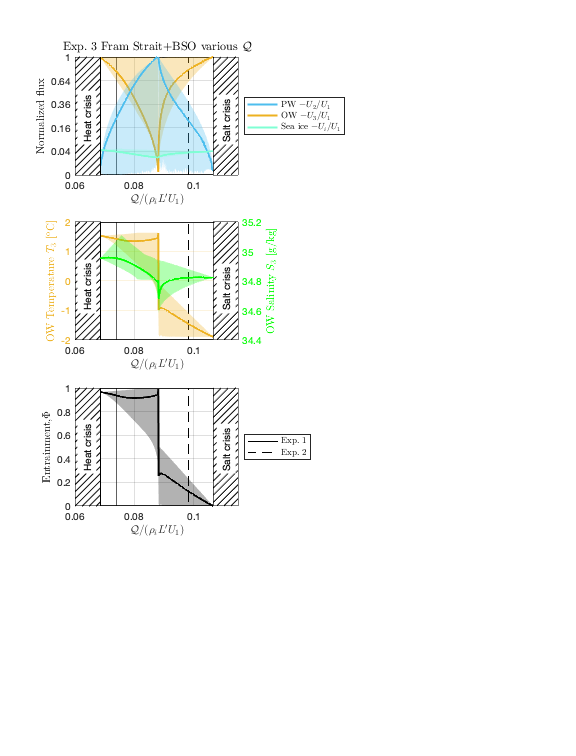

plot_POC_solutions1(model3,model1,model2) ;

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

model4 = build_POC_model('NH_FSBSO_sens') ;

 Solutions for experiment: [Exp.~4 Fram Strait+BSO sensitivity] with file suffices: [NH_FSBSO_sens]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   3.1667   5.1458   7.1250
 Atlantic Water to shelf:    2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   0.0000   1.9014   7.1246
 Polar    Water:            -1.9174  -1.8654  -1.8129 |  33.3813  34.2866  35.1791 |  -7.3082  -2.0430  -0.0000
 Overflow Water:            -1.9483   0.0488   2.4289 |  33.7579  34.8469  35.9065 |  -7.1726  -3.4186  -0.0000
 Shelf    Water:            -1.8347  -1.9558  -2.2015 |  33.7579  35.8370  39.9999 |  -7.1559  -1.

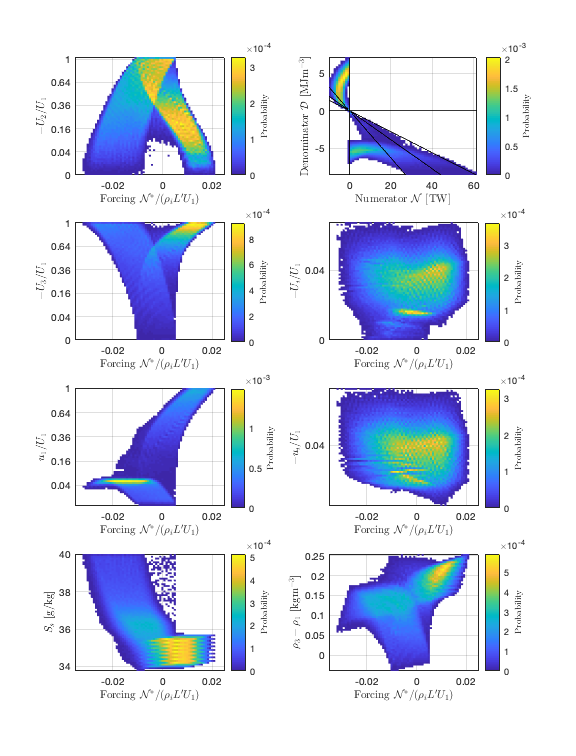

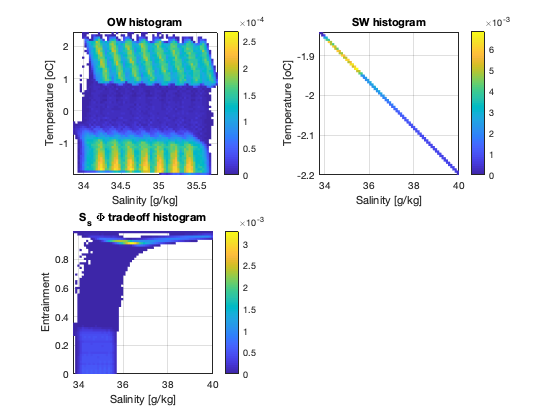

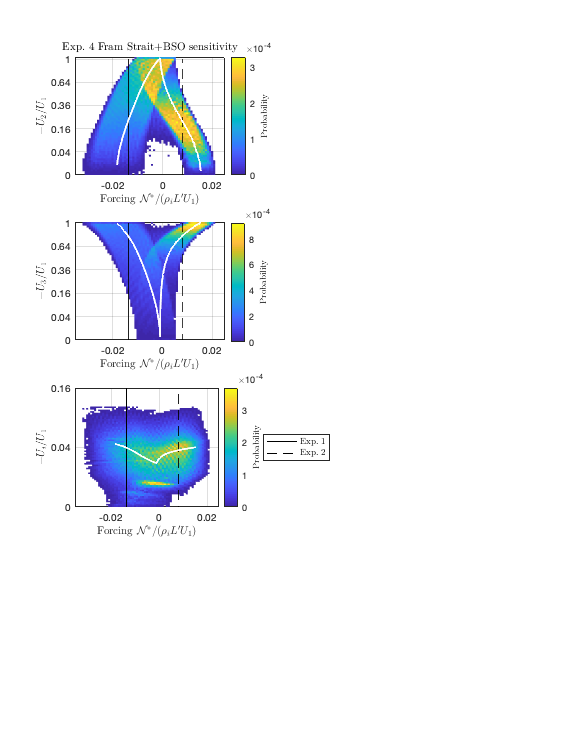

plot_POC_solutions2(model4,model3,model1,model2)

Compare numerical results to theory

 Exp.~4 has [525199] solutions, found: [215] salt crises, [101] heat crises, [646] OW emergencies.


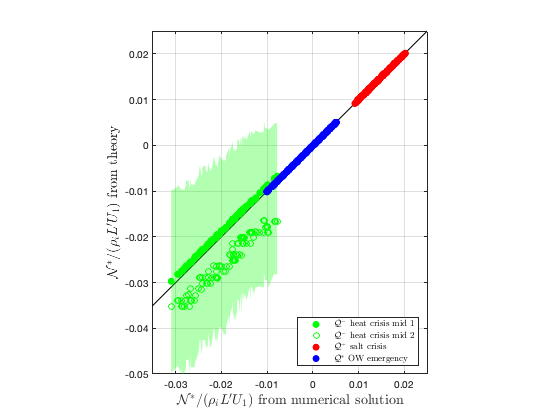

plot_POC_solutions_and_theory(model4)

Exp 5: Northern hemisphere Fram Strait/Barents Sea Opening with various S_2 values.

model5 = build_POC_model('NH_FSBSO_S2_range') ;

 Solutions for experiment: [Exp.~5 Fram Strait+BSO various $S_2$] with file suffices: [NH_FSBSO_S2_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0170   0.9227   1.8240
 Polar    Water:            -1.8675  -1.8096  -1.7518 |  30.3235  32.3235  34.3235 |  -4.4929  -1.6253  -0.0000
 Overflow Water:            -0.4580   0.7594   1.6043 |  34.6497  34.7867  35.0714 |  -4.7731  -3.1780  -0.3876
 Shelf    Water:            -1.8884  -1.9459  -2.2015 |  34.6814  35.6687  40.0000 |  -1.805

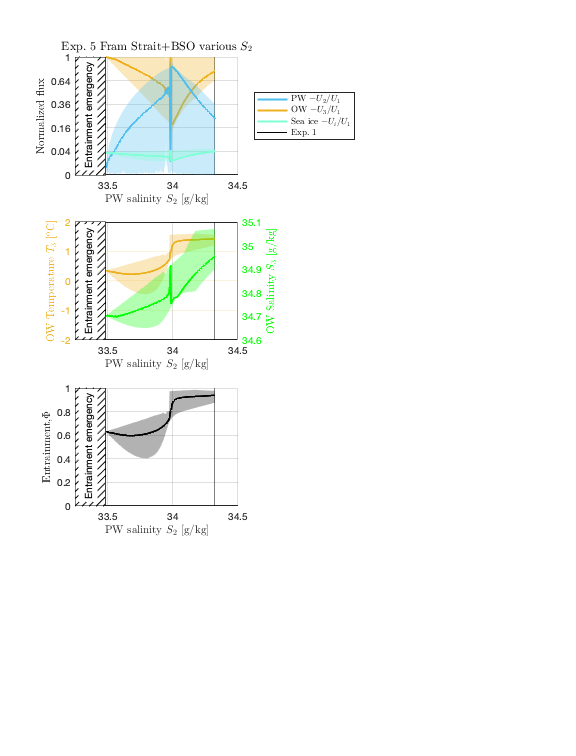

plot_POC_solutions3(model5,model1)

Exp 6: Southern hemisphere.

model6 = build_POC_model('SH_can') ;

 Solutions for experiment: [Exp.~6 Antarctic] with file suffices: [SH_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      0.5000          |           34.8386          |           26.0000
 Atlantic Water to shelf:             0.5000          |           34.8386          |   2.9349   6.5040   9.9643
 Polar    Water:                     -1.8868          |           34.6548          | -23.1477 -15.7313  -0.0198
 Overflow Water:            -1.8731  -1.2997  -0.8552 |  34.7965  34.8998  35.0318 | -25.7961 -10.3110  -2.9648
 Shelf    Water:            -1.8951  -1.9053  -1.9370 |  34.7969  34.9727  35.5158 |  -9.7587  -6.4502  -2.9242
 Ambient Water:     

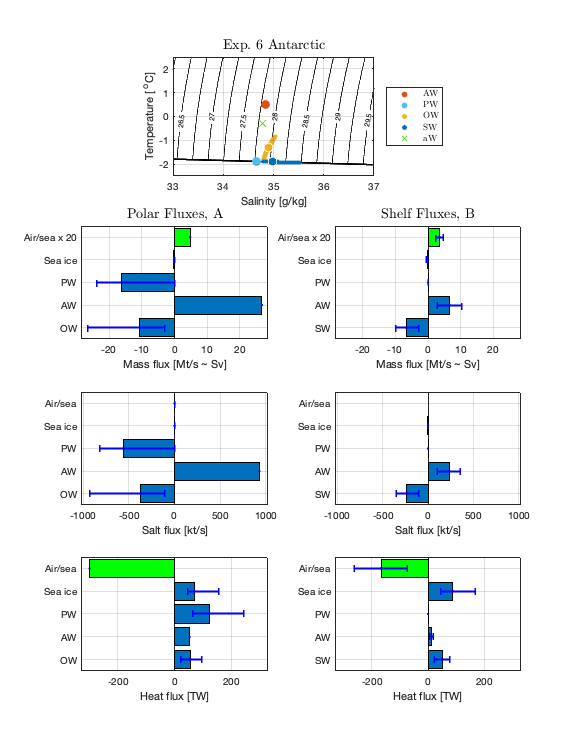

plot_POC_solution(model6)

Exp V: Southern hemisphere with warm AW following reviewer 2.

modelV = build_POC_model('SH_mod') ;

 Solutions for experiment: [Exp.~V Antarctic warm AW] with file suffices: [SH_mod]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           34.8386          |           26.0000
 Atlantic Water to shelf:             1.5000          |           34.8386          |   0.1851   1.1426   4.9513
 Polar    Water:                     -1.8789          |           34.5184          | -15.7649 -11.8965  -0.0002
 Overflow Water:            -0.0468   0.2066   0.3471 |  34.8101  34.8909  35.0563 | -25.8524 -14.1720 -10.3789
 Shelf    Water:            -1.9643  -2.0157  -2.2015 |  35.9819  36.8591  40.0000 |  -4.7400  -1.0511  -0.1515
 Ambient Wat

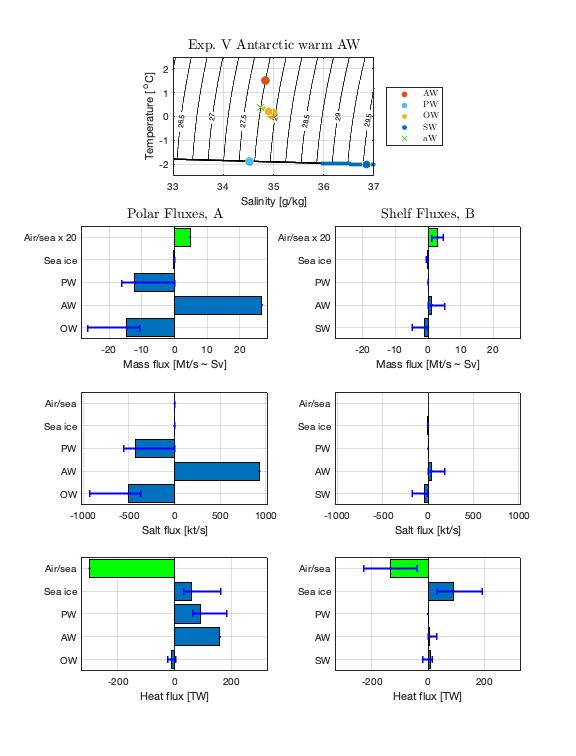

plot_POC_solution(modelV)

Exp W: Eldevik & Nilsen (2013) parameters

modelW = build_POC_model('NH_FSBSO_EN13') ;

 Solutions for experiment: [Exp.~W Fram Strait+BSO] with file suffices: [NH_FSBSO_EN13]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      7.0000          |           35.2000          |            8.5000
 Atlantic Water to shelf:             7.0000          |           35.2000          |   6.5196   6.5217   6.5237
 Polar    Water:                     -1.8221          |           33.5407          |  -0.0149  -0.0149  -0.0149
 Overflow Water:            -0.5021  -0.5021  -0.5021 |  34.6475  34.6475  34.6475 |  -8.6188  -8.6188  -8.6188
 Shelf    Water:            -1.8863  -1.8863  -1.8863 |  34.6460  34.6460  34.6460 |  -6.6218  -6.6218  -6.6218
 Ambien

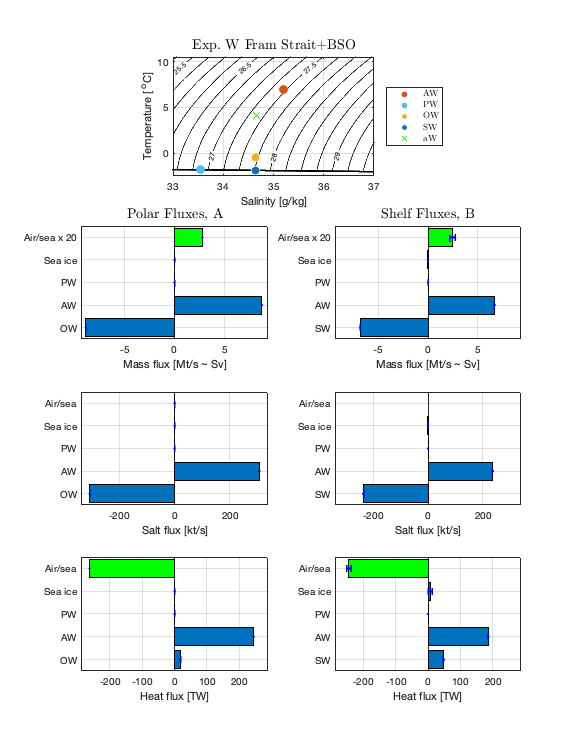

plot_POC_solution(modelW)

Exp X: Modified Northern hemisphere Fram Strait/Barents Sea Opening (intermediate Q).

modelX = build_POC_model('NH_FSBSO_int') ;

 Solutions for experiment: [Exp.~X Fram Strait+BSO intermediate ${\cal Q}$] with file suffices: [NH_FSBSO_int]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.0141   0.0470   2.1228
 Polar    Water:                     -1.8675          |           34.3235          |  -4.4589  -4.4061  -0.0046
 Overflow Water:            -0.0021   1.4085   1.6355 |  34.8068  34.8277  34.9595 |  -4.7302  -0.4207  -0.3690
 Shelf    Water:            -1.8994  -1.9361  -2.2015 |  34.8711  35.5010  40.0000 |  -2.0891  -

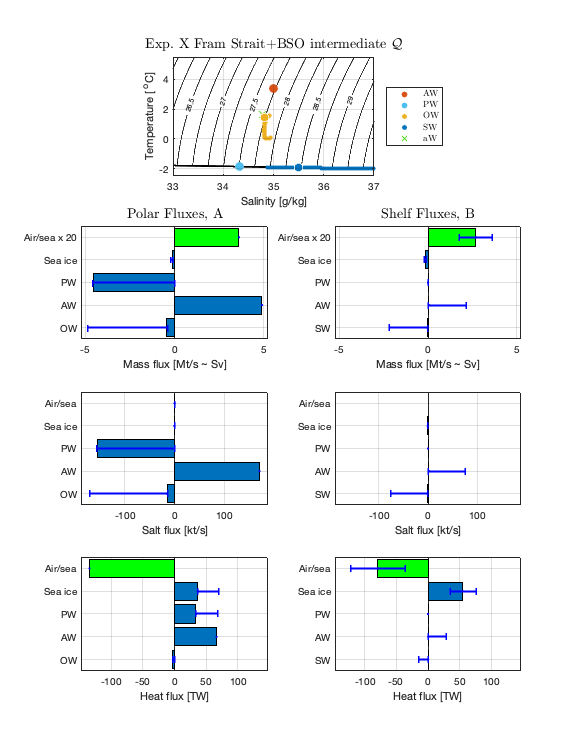

plot_POC_solution(modelX)

Exp Y: Modified Northern hemisphere Fram Strait/Barents Sea Opening (small S2).

modelY = build_POC_model('NH_FSBSO_small_S2') ;

 Solutions for experiment: [Exp.~Y Fram Strait+BSO small $S_2$] with file suffices: [NH_FSBSO_small_S2]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   1.7742   1.7807   1.7835
 Polar    Water:                     -1.8189          |           32.6475          |  -0.0155  -0.0155  -0.0005
 Overflow Water:             0.3522   0.3522   0.3591 |  34.7023  34.7023  34.7032 |  -4.7726  -4.7584  -4.7584
 Shelf    Water:            -1.9097  -1.9097  -1.9100 |  35.0472  35.0472  35.0525 |  -1.7576  -1.7576 

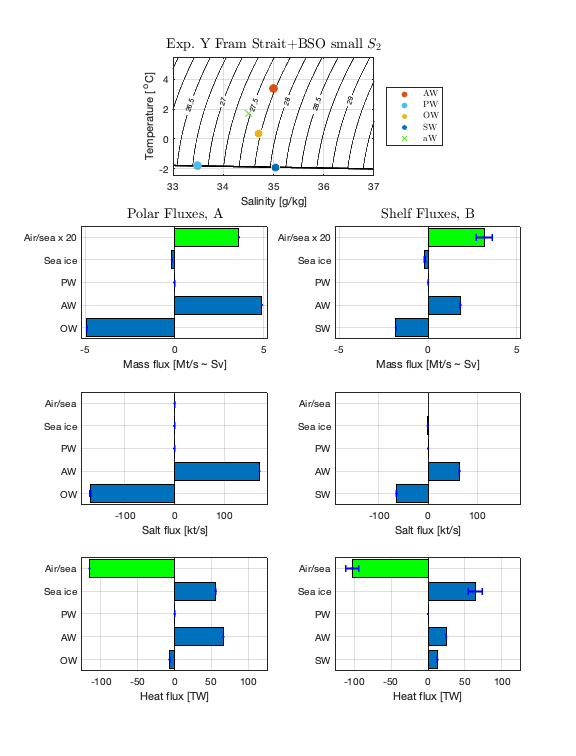

plot_POC_solution(modelY)

Exp Z: Southern hemisphere with many Q values

modelZ = build_POC_model('SH_range') ;

 Solutions for experiment: [Exp.~Z Antarctic various ${\cal Q}$] with file suffices: [SH_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |  26.0000  26.0000  26.0000
 Atlantic Water to shelf:    0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |   0.0124  10.0831  25.9607
 Polar    Water:            -1.8868  -1.8868  -1.8868 |  34.6548  34.6548  34.6548 | -26.1265  -9.4805  -0.0000
 Overflow Water:            -1.9056  -1.0998  -0.2912 |  34.7205  34.9327  35.1176 | -25.8574 -16.4835  -0.0000
 Shelf    Water:            -1.8906  -1.9617  -2.2015 |  34.7193  35.9375  40.0000 | -25.8084  -9.9814

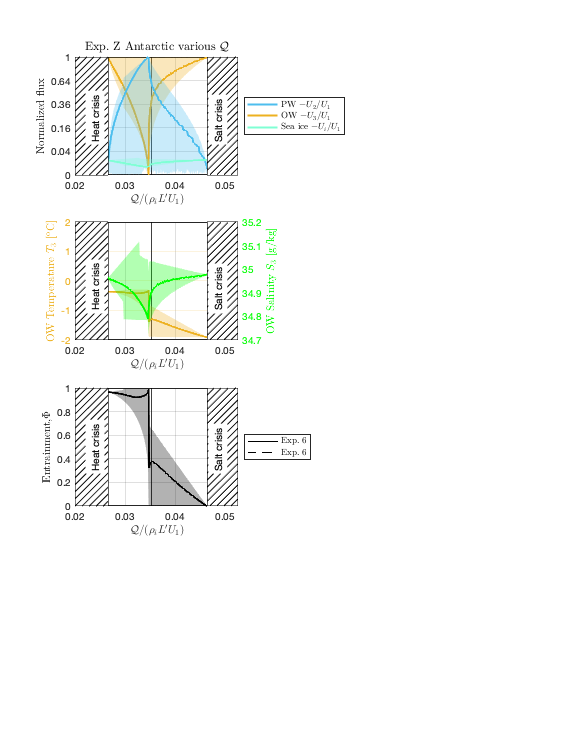

plot_POC_solutions1(modelZ,model6,model6)